# Sample 11-5

## 画像ノイズ除去

事前分布

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Image denoising

Prior distribution

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

clear 
close all
import msip.download_img
msip.download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


### パラメータ設定

(Parameter settings)

- sgm: ノイズ標準偏差 $\sigma_w$ (Standard deviation of noise)

- nlevels: ウェーブレット段数 (Wavelet levels)

% Parameter settings
nlevels = 3; 

## 画像の読込

(Read image)

img = "lena";
u = im2double(imread(['./data/' char(img) '.png']));
if size(u,3) == 3
    u = rgb2gray(u);
end

## 分析処理

(Analysis process)

直交ウェーブレット変換Symlet を利用．(Uses Symlet, which is an orthogonal wavelet transform.)

% Preperation of filters for wavelets
iswtb = license('checkout','wavelet_toolbox');
if iswtb % Functions in Wavelet Toolbox are used
    dwtmode('per')
    wname = "sym4";
    [h0,h1,f0,f1] = wfilters(wname);
    %save(['./data/' char(wname) '.mat'],'h0','h1','f0','f1')
else
    import msip.ezwavedec2
    import msip.ezwaverec2
    S = load('./data/sym4.mat');
    h0 = S.h0;
    h1 = S.h1;
    f0 = S.f0;
    f1 = S.f1;
    clear H  F
    % Analysis bivariate filters
    H.h00 = h0(:)*h0(:).';
    H.h01 = h0(:)*h1(:).';
    H.h10 = h1(:)*h0(:).';
    H.h11 = h1(:)*h1(:).';
    % Synthesis bivariate filters
    F.f00 = f0(:)*f0(:).';
    F.f01 = f0(:)*f1(:).';
    F.f10 = f1(:)*f0(:).';
    F.f11 = f1(:)*f1(:).';
end

                      
**********************
**  DWT 拡張モード: 周期化  **
**********************
                      


分析処理 (Analysis process)

if iswtb
    [coefs,scales] = wavedec2(u,nlevels,h0,h1);
    % Reconstruction to check PR
    r = waverec2(coefs,scales,f0,f1);
else
    [coefs,scales] = ezwavedec2(u,nlevels,H);
    % Reconstruction to check PR%
    r = ezwaverec2(coefs,scales,F);
end
assert(norm(u-r,"fro")^2/numel(u)<1e-18,'Perfect reconstruction is violated.')

変換係数の抽出 (Extraction  of coefficients)

s = extractcoefs(coefs,scales);

### 変換係数の分布

(Distribution of Coefs.)

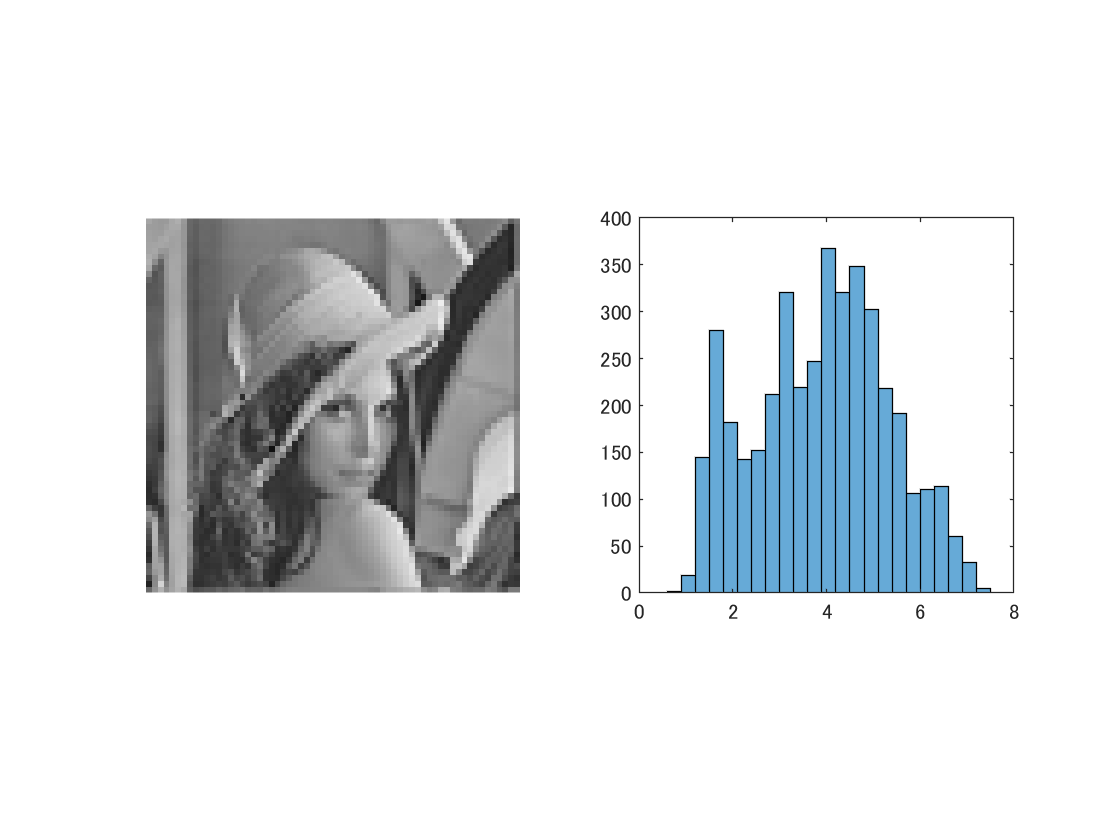

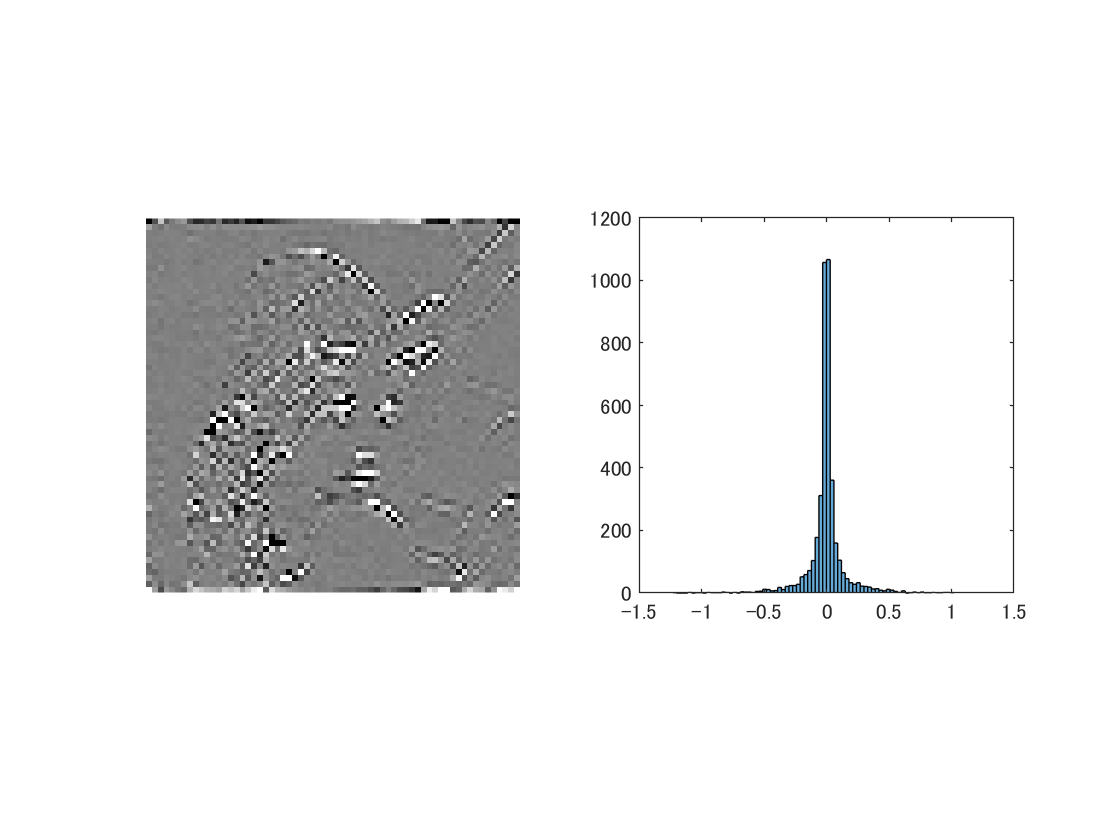

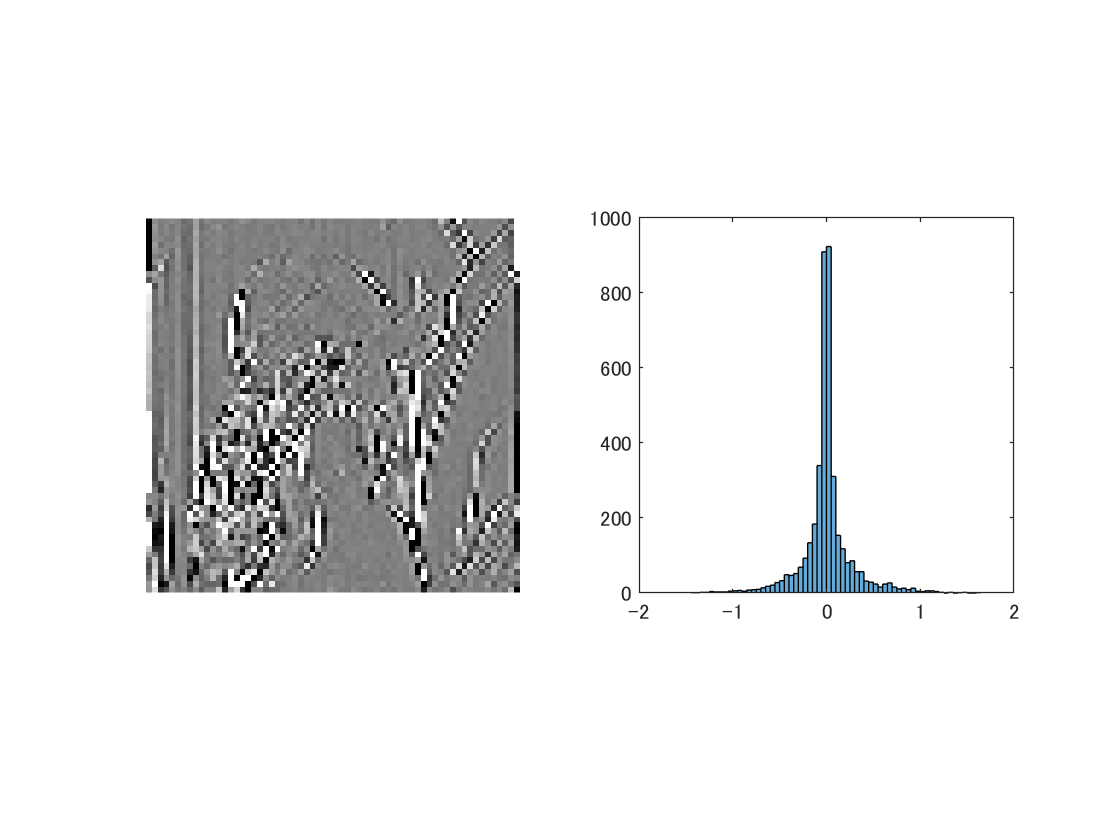

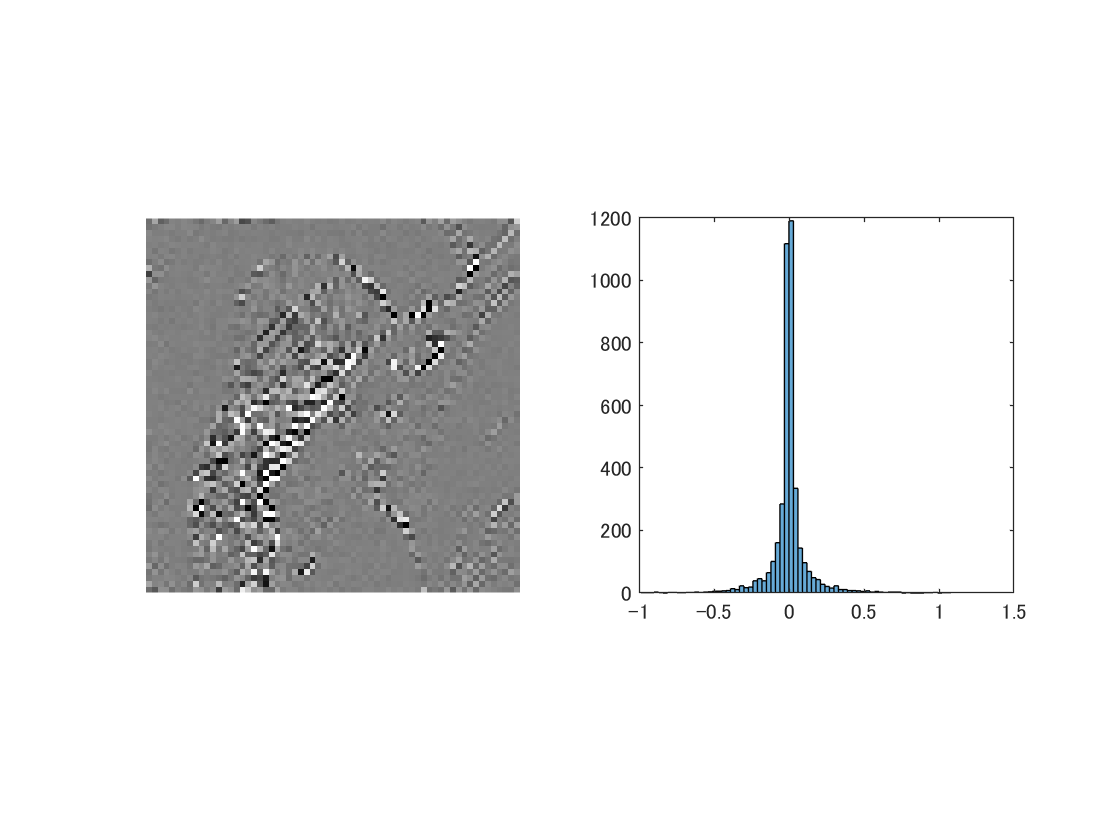

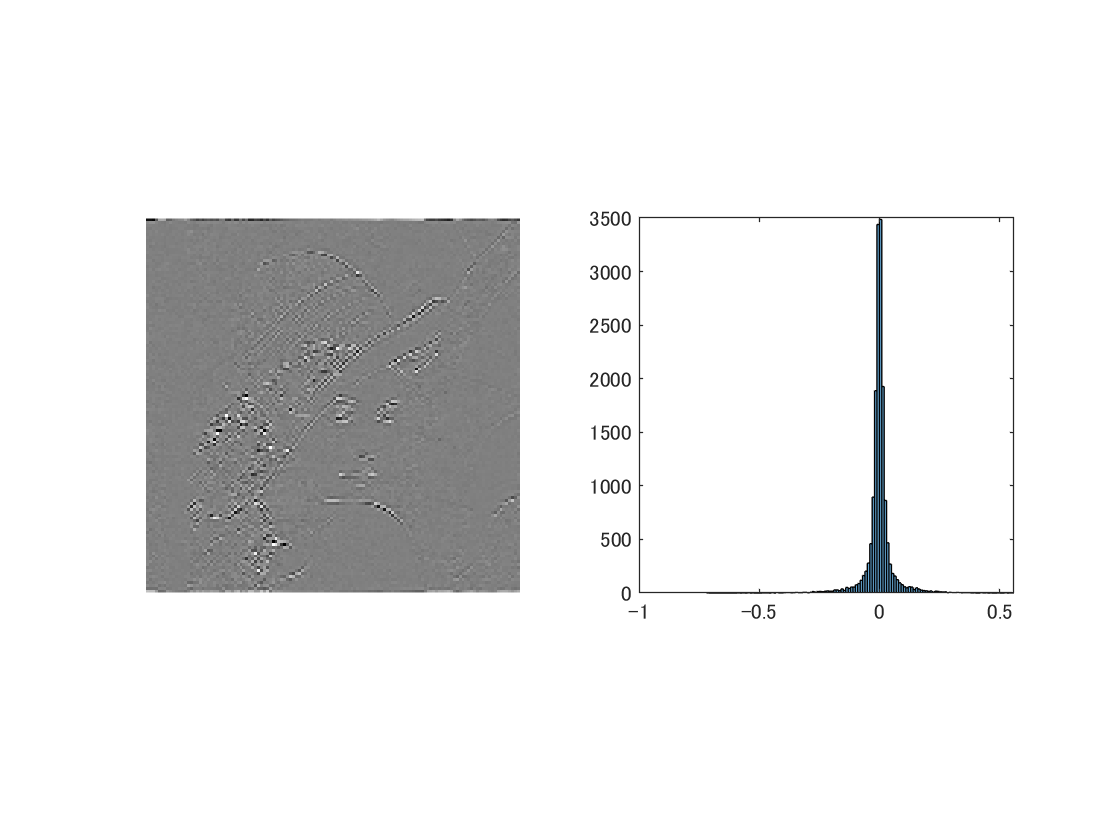

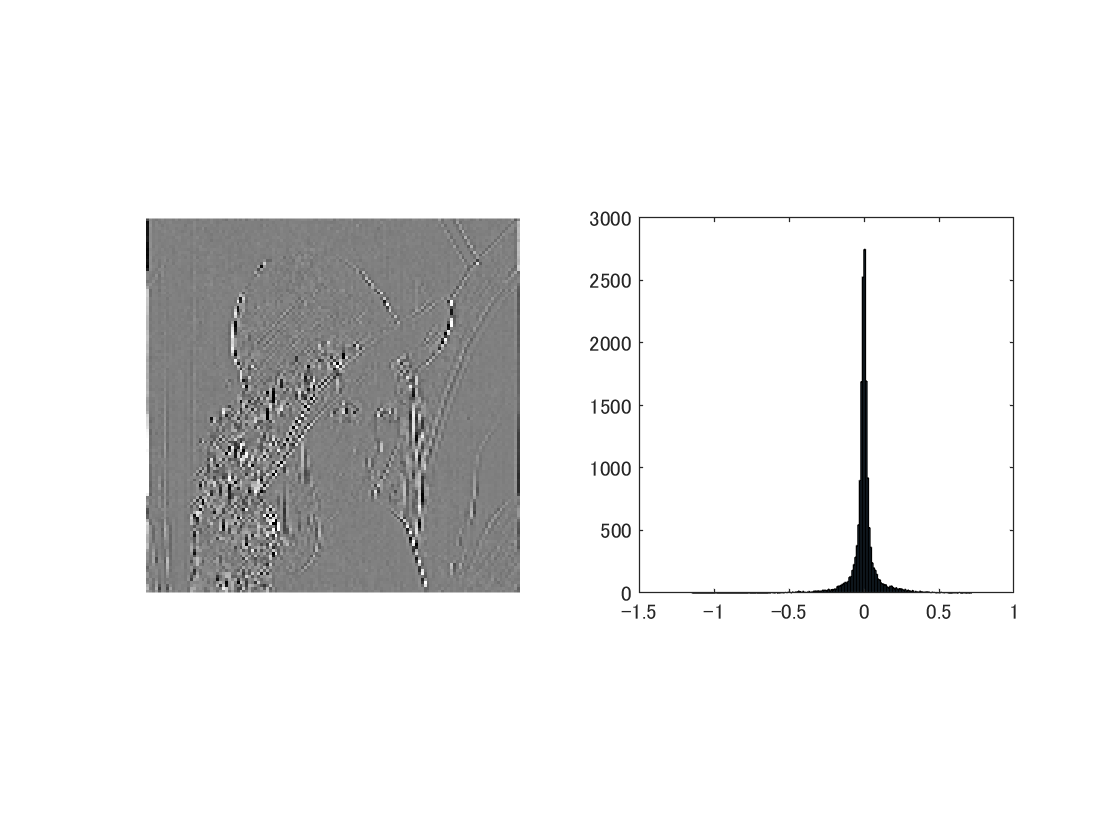

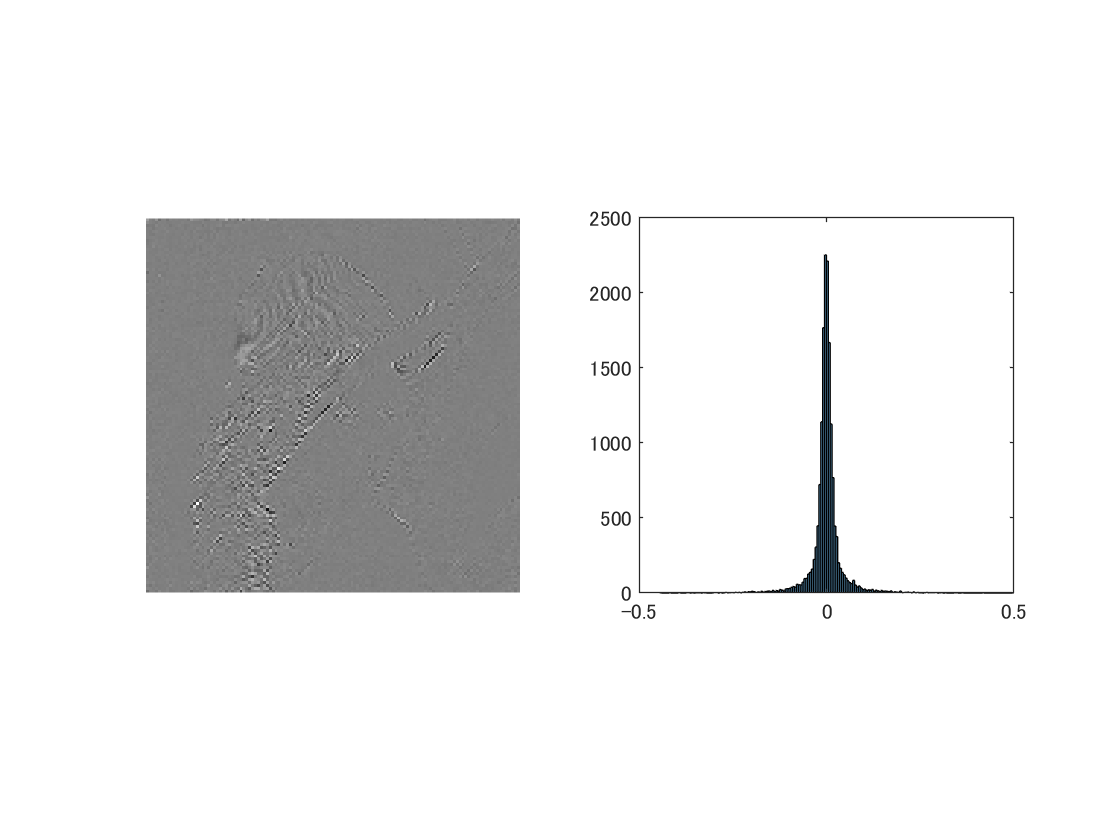

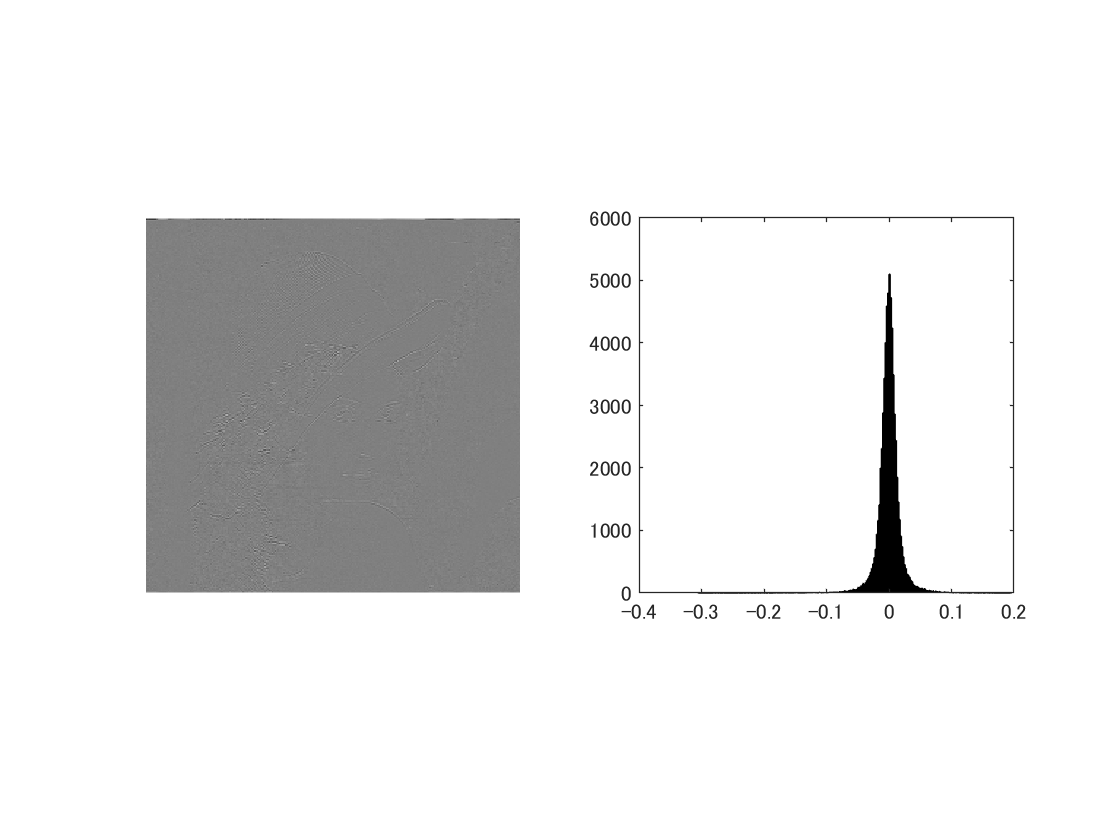

nchs = length(s);
for ich = 1:nchs
    figure(ich)
    subplot(1,2,1)
    if ich == 1
        imshow(s{ich}*pow2(-nlevels))
    else
        imshow(s{ich}+.5)
    end 
    subplot(1,2,2)
    histogram(s{ich}(:))
    axis square
end

### ラプラス分布

(Laplace distribution)

変換係数はラプラス分布に従う乱数と仮定．(Coefs. are assumed to be random numbers drawn from a Laplace distribution.)

- 
$$\mathbf{s}\sim\mathrm{Lap}\left(\mathbf{s}|\mathbf{\mu}=\mathbf{0},b\right)$$


- 
$$\mathrm{Lap}\left(\mathbf{s}|\mathbf{\mu}=\mathbf{0},b\right)=\frac{1}{2b}\exp\left(-\frac{\|\mathbf{s}-\mathbf{\mu}\|_1}{b}\right)$$


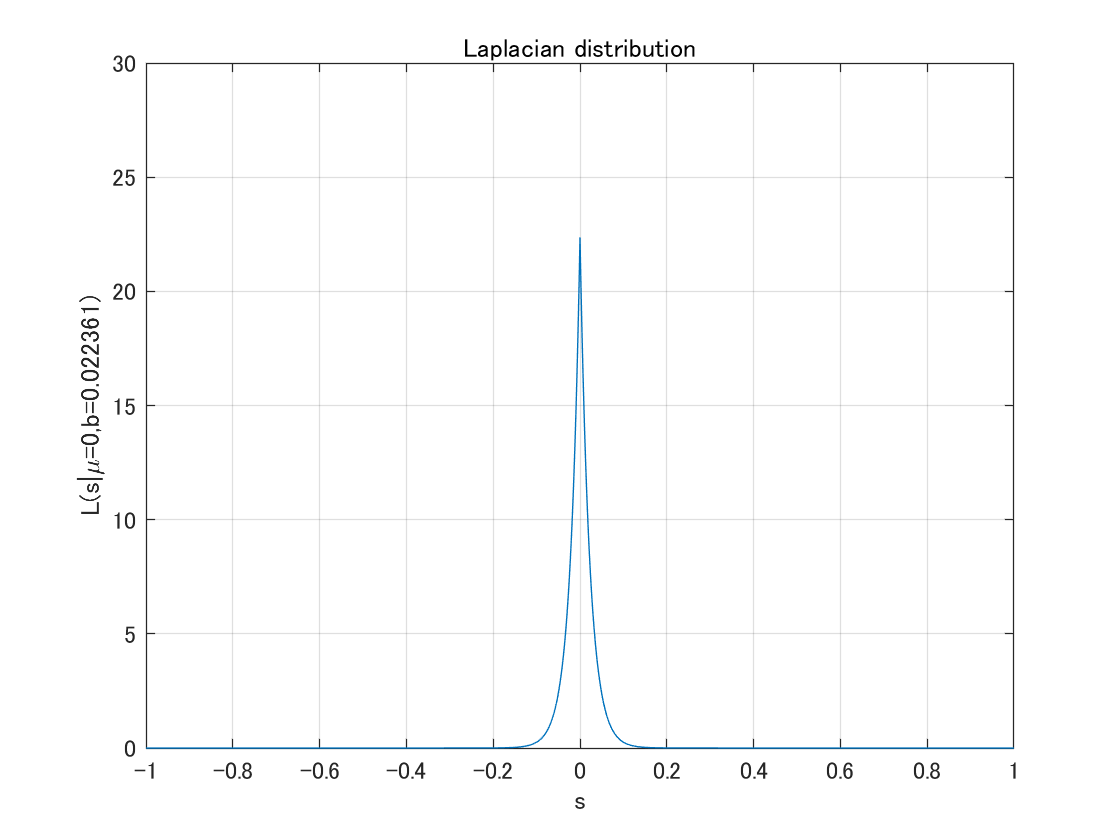

% Laplacian parameters
mu = 0;
sgm2 = 0.001;
b = sqrt(sgm2/2);
ifig = nchs + 1;
% Laplacian distribution
spdf = @(x) 1/(2*b)*exp(-abs(x-mu)/b);
figure(ifig)
h = fplot(spdf);
xlabel('s')
ylabel(['L(s|\mu=0,b=' num2str(b) ')'])
title('Laplacian distribution')
grid on
axis([-1 1 0 30])

## 観測画像

(Observation image)

パラメータ設定 (Parameter settings)

sgmuint8 = 30; 
sgm = sgmuint8/255;

ノイズ付加 (Add noise)

v = imnoise(u,'gaussian',0,sgm^2);

分析処理 (Analysis process)

if iswtb
    [coefs,scales] = wavedec2(v,nlevels,h0,h1);
else
    [coefs,scales] = ezwavedec2(v,nlevels,H);
end

### ウェーブレット縮退処理

(Wavelet shrinkage)

問題設定 (Problem settings)

- 
$$\hat{\mathbf{s}}=\arg\min_{\mathbf{s}}\frac{1}{2}\|\mathbf{v}-\mathbf{Ds}\|_2^2+\lambda\|\mathbf{s}\|_1$$


- $\mathbf{DD}^T=\mathbf{D}^T\mathbf{D}=\mathbf{I}$ (Orthonormal)

パラメータ設定 (Parameter settings)

isbayesshrink = false;
if ~isbayesshrink
    isaprxleft = true;
    lambda = 10^-0.8
end

lambda = 0.1585

ソフト閾値処理 (Soft-thresholding)

            
$$\hat{\mathbf{s}} = \mathcal{T}_\lambda(\mathbf{s})=\mathrm{sign}(\mathbf{s})\odot\max(\mathrm{abs}(\mathbf{s})-\lambda\mathbf{1},\mathbf{0})$$


% サブバンド適応ソフト縮退処理
if isbayesshrink
    import msip.bayesshrink
    coefs = bayesshrink(coefs,scales); 
else
    if isaprxleft
        mask = ones(size(coefs));
        mask(1:prod(scales(1,:))) = 0;
        lambda = lambda * mask;
    end
    softshrink = @(x) sign(x).*max(abs(x)-lambda,0);
    coefs = softshrink(coefs);
end

合成処理 (Synthesis process)

if iswtb
    r = waverec2(coefs,scales,f0,f1);
else
    r = ezwaverec2(coefs,scales,F);
end

### 画像表示

(Image show)

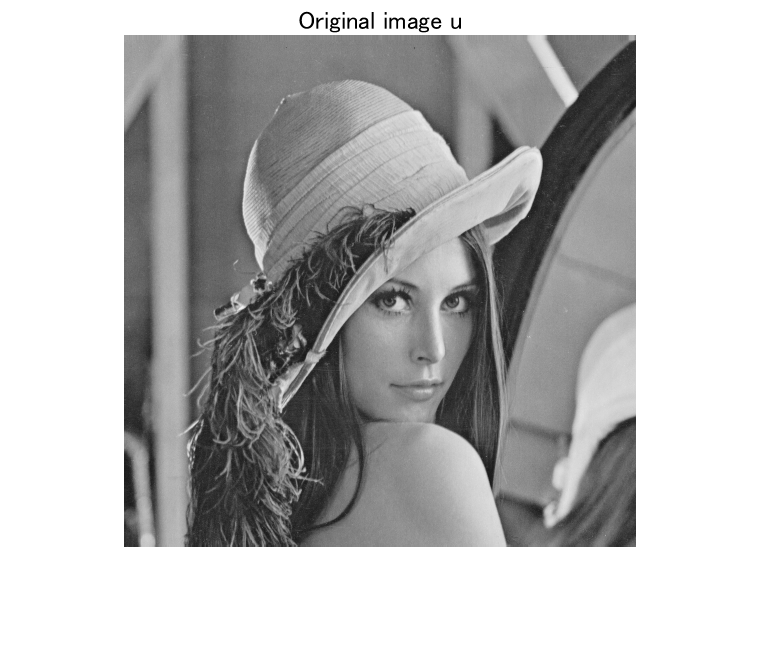

ifig = ifig + 1;
figure(ifig)
imshow(u);
title('Original image u')

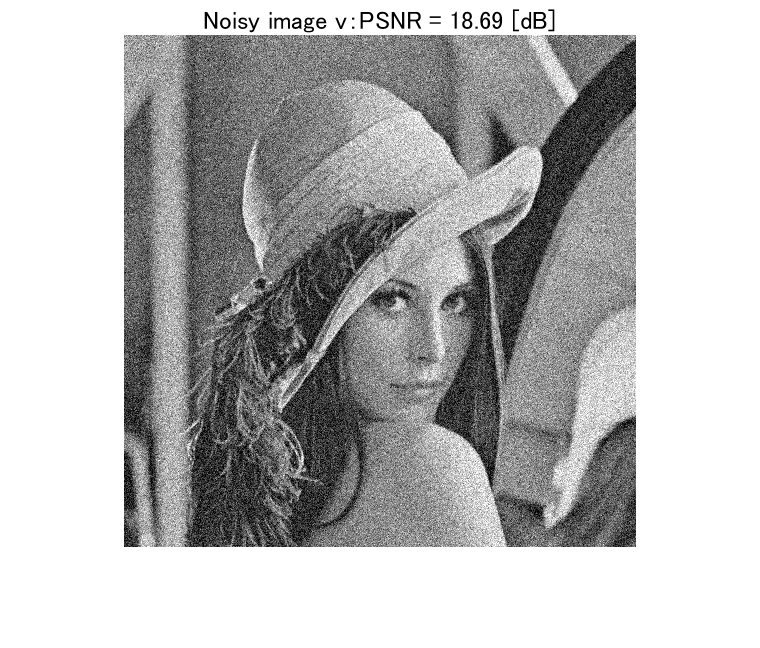

ifig = ifig + 1;
figure(ifig) 
imshow(v)
title(sprintf('Noisy image v：PSNR = %5.2f [dB]',psnr(u,v)))

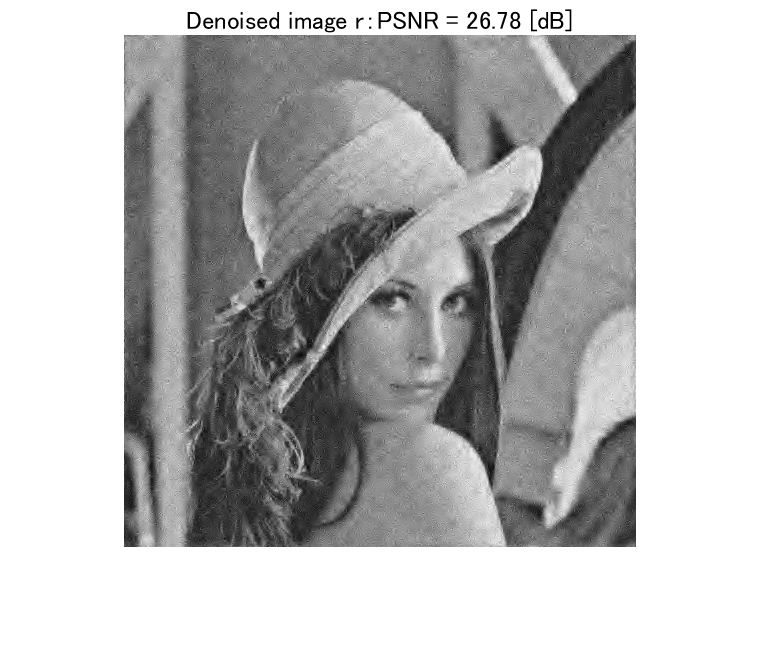

ifig = ifig + 1;
figure(ifig) 
imshow(r)
title(sprintf('Denoised image r：PSNR = %5.2f [dB]',psnr(u,r)))

### ウェーブレット画像ノイズ除去関数

(Wavelet image denoising function)

参考資料 (Reference)

if iswtb
    help wthcoef2
    help wdenoise2
end

wthcoef2 - Wavelet coefficient thresholding 2-D

    This MATLAB function returns the horizontal (vertical or diagonal, respectively)
    coefficients obtained from the wavelet decomposition structure [C,S] (see
    wavedec2 for more information), by soft (if SORH ='s') or hard (if SORH ='h')
    thresholding defined in vectors N and T.

    NC = wthcoef2('type',C,S,N,T,SORH)
    NC = wthcoef2('type',C,S,N)
    NC = wthcoef2('a',C,S)
    NC = wthcoef2('t',C,S,N,T,SORH)

    参考 <a href="https://www.mathworks.com/help/releases/R2020a/wavelet/ref/wavedec2.html">wavedec2</a>, <a href="https://www.mathworks.com/help/releases/R2020a/wavelet/ref/wthresh.html">wthresh</a>

    wthcoef2 のドキュメンテーション



wdenoise2 - Wavelet image denoising

    This MATLAB function denoises the grayscale or RGB image IM using an empirical
    Bayesian method.

    IMDEN = wdenoise2(IM)
    IMDEN = wdenoise2(IM,LEVEL)
    [IMDEN,DENOISEDCFS] = wdenoise2(___)
    [IMDEN,DENOISEDCFS,ORIGCFS] = wdenoise2(___)
    [IMDEN,DENOISEDCFS,ORIGCFS,S] = wdenoise2(___)
    [IMDEN,DENOISEDCFS,ORIGCFS,S,SHIFTS] = wdenoise2(___)
    [___] = wdenoise2(___,Name,Value)
    wdenoise2(___)

    参考 <a href="https://www.mathworks.com/help/releases/R2020a/wavelet/ref/wavedec2.html">wavedec2</a>, <a href="https://www.mathworks.com/help/releases/R2020a/wavelet/ref/wdenoise.html">wdenoise</a>

    wdenoise2 のドキュメンテーション



### 変換係数の抽出

(Extraction of Coefs.)

function s = extractcoefs(coefs,scales)
nscales = size(scales,1)-1;
s = cell(3*(nscales-1)+1,1);
sidx = 1;
ndims = scales(1,:);
eidx = sidx + prod(ndims) - 1;
s{1} = reshape(coefs(sidx:eidx),ndims);
sidx = eidx + 1; 
ich = 2;
for iscale = 2:nscales
    ndims = scales(iscale,:);
    for iband = 1:3
        eidx = sidx + prod(ndims) - 1;
        s{ich} = reshape(coefs(sidx:eidx),ndims);
        sidx = eidx + 1;
        ich = ich + 1;
    end
end
end

© Copyright, Shogo MURAMATSU, All rights reserved.